clear all
close all
%read data
depth2 = readmatrix("depth2_200MHZ.xlsx");
depth3 = readmatrix("depth3_200MHZ.xlsx");
depth4 = readmatrix("depth4_200MHZ.xlsx");

% set up values for depth 2
depth2size = size(depth2);
qfactor = zeros(3, 3);
for i = 1:3
    qfac = depth2((3*i-2):3*i, 9);
    qfactor(:,i) = qfac;
end

density = zeros(3, 3);
for i = 1:3
    dens = depth2((3*i-2):3*i, 3);
    density(:,i) = dens;
end

polywidth = zeros(3, 3);
for i = 1:3
    polyw = depth2((3*i-2):3*i, 4);
    polywidth(:,i) = polyw;
end

turns = zeros(3, 3);
for i = 1:3
    trns = depth2((3*i-2):3*i, 2);
    turns(:,i) = trns;
end

% disp(resonance_2);

% polywidth = 0.1:0.1:1;
% interval = 20:5:50;

sc = surfc(density, polywidth, turns,'EdgeColor', "none", 'FaceColor', 'interp');
title('DEPTH 2: Turn density vs polywidth vs # of turns for 200 MHZ');
xlabel('turn density');
ylabel('polywidth');
zlabel('# of turns');
% sc = surf(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax'

sc =   2×1 graphics array:

  Surface
  Contour


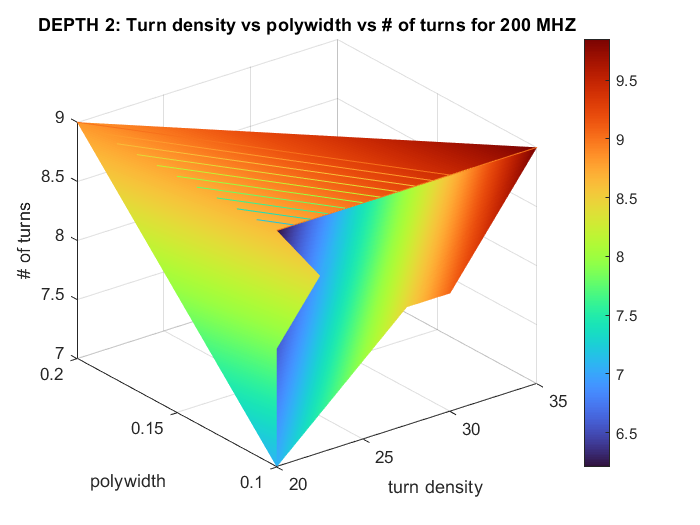


sc(1).CData = qfactor;
colormap turbo;
colorbar;



% set up values for depth 3
depth3size = size(depth3);
qfactor = zeros(11, 2);
for i = 1:2
    qfac = depth3((11*i-10):11*i, 9);
    qfactor(:,i) = qfac;
end

density = zeros(11, 2);
for i = 1:2
    dens = depth3((11*i-10):11*i, 3);
    density(:,i) = dens;
end

polywidth = zeros(11, 2);
for i = 1:2
    polyw = depth3((11*i-10):11*i, 4);
    polywidth(:,i) = polyw;
end

turns = zeros(11, 2);
for i = 1:2
    trns = depth3((11*i-10):11*i, 2);
    turns(:,i) = trns;
end
    
% disp(resonance_2);

% polywidth = 0.1:0.1:1;
% interval = 20:5:50;

sc = surfc(density, polywidth, turns,'EdgeColor', "none", 'FaceColor', 'interp');
title('DEPTH 3: Turn density vs polywidth vs # of turns for 200 MHZ');
xlabel('turn density');
ylabel('polywidth');
zlabel('# of turns');
% sc = surf(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax'

sc =   2×1 graphics array:

  Surface
  Contour


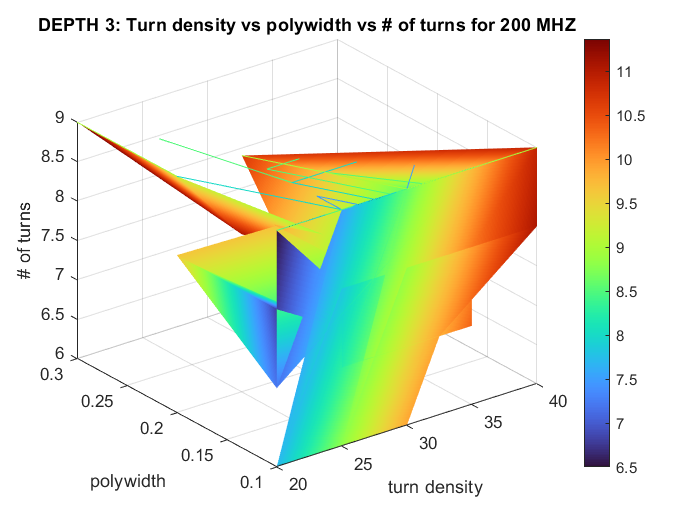


sc(1).CData = qfactor;
colormap turbo;
colorbar;



% set up values for depth 4
depth3size = size(depth3);
qfactor = zeros(2, 2);
% qfactor = 12.29489:0.30058:13.49721
for i = 1:2
    qfac = depth4((2*i-1):2*i, 9);
    qfactor(:,i) = qfac;
end

density = zeros(2, 2);
for i = 1:2
    dens = depth4((2*i-1):2*i, 3);
    density(:,i) = dens;
end

polywidth = zeros(2, 2);
for i = 1:2
    polyw = depth4((2*i-1):2*i, 4);
    polywidth(:,i) = polyw;
end

turns = zeros(2, 2);
for i = 1:2
    trns = depth4((2*i-1):2*i, 2);
    turns(:,i) = trns;
end

% disp(resonance_2);

% polywidth = 0.1:0.1:1;
% interval = 20:5:50;

sc = surfc(density, polywidth, turns,'EdgeColor', "none", 'FaceColor', 'interp');
title('DEPTH 4: Turn density vs polywidth vs # of turns for 200 MHZ');
xlabel('turn density');
ylabel('polywidth');
zlabel('# of turns');
% sc = surf(interval,polywidth,qfactor_2_6,'EdgeColor',"none",'FaceColor','interp');
sc(2).ZLocation = 'zmax'

sc =   2×1 graphics array:

  Surface
  Contour


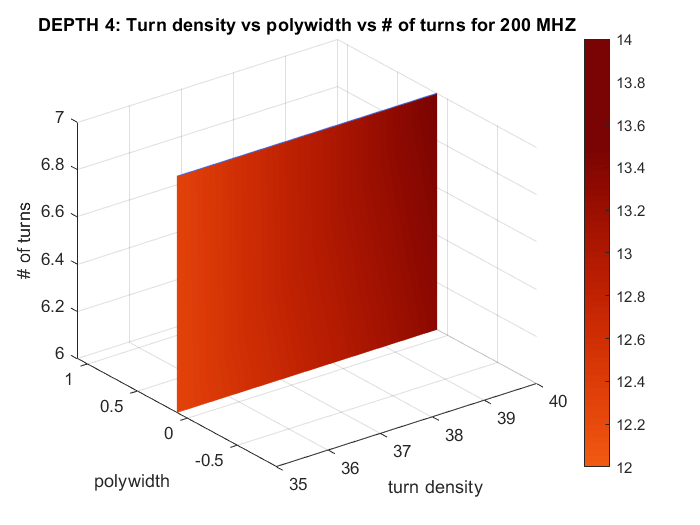


sc(1).CData = qfactor;

colormap turbo;
c = colorbar;
c.Limits = [12 14];